## PART 2: Trajectory Planning 

In this part, the goal is to plan a trajectory which approximates the circular path from Problem 3 by means of 5 knot-points at *ϕ*0, *ϕ*9, *ϕ*18, *ϕ*27, *ϕ*36. 

### Problem 6:

Use the inverse computed joint confifigurations *q *(0) , *q *(9) , *q *(18) , *q *(27) , *q *(36) from Problem 3, to fifind suitable interpolation polynomials for the following segments: 

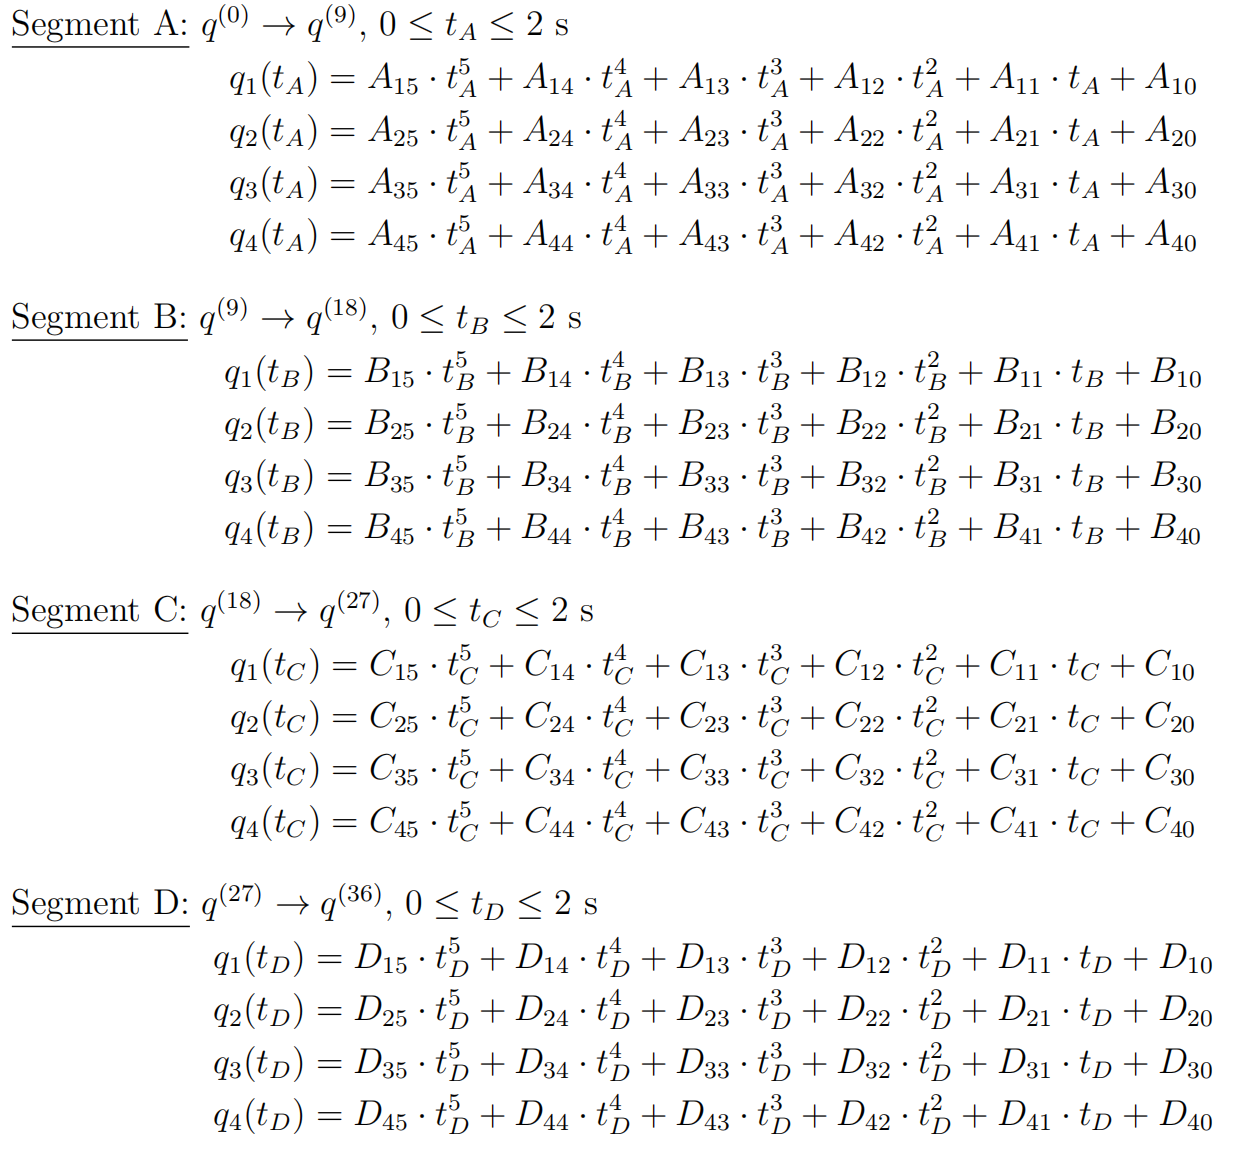

Determine the coeffiffifficients *A**ij *, *B**ij *, *C**ij *, *D**ij *so that 

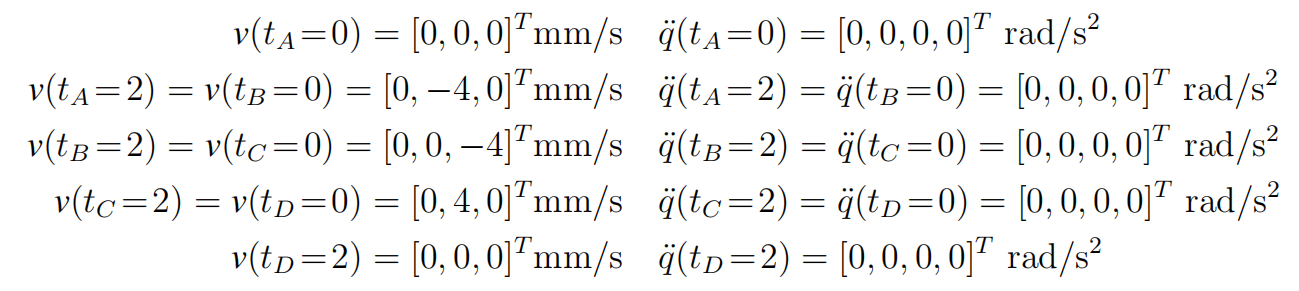

Hint: Note that end-effffector velocities *v *need to be converted to joint velocities ˙*q *and that requiring zero joint acceleration at knot points is maybe not the best but the simplest option. 

tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is
                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0];
VA = [0;-4;0];
VB = [0;0;-4];
VC = [0;4;0];
VD = [0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);
JB = getJacobian(19);
JC = getJacobian(28);
JD = getJacobian(37);
%jaconbian matrix for calculating joint velocities ˙q
v0=0;
vA=JA/VA;
vB=JB/VB;
vC=JC/VC;
vD=JD/VD;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA,ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA,ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA,ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA,ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA,vB,ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA,vB,ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA,vB,ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA,vB,ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB,vC,ain,aout);
C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB,vC,ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB,vC,ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB,vC,ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC,vD,ain,aout);
D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC,vD,ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC,vD,ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC,vD,ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

### Problem 7:

Plot the actual path of the end-effector as a function of time for the interpolated trajectory from Problem 6 and its deviation from the desired circular path. Try to improve the approximation either by using more knot-points or by using different interpolation functions than those found in Problem 6.